# Create Simulink Environment and Train Agent

This example shows how to convert the PI controller in the `watertank` Simulink® model to a reinforcement learning deep deterministic policy gradient (DDPG) agent. For an example that trains a DDPG agent in MATLAB®, see [Train DDPG Agent to Balance Double Integrator Environment](docid:rl_ug#mw_0b71212e-521a-4a57-bde7-5dde0c1e0c90).

## Water Tank Model

The original model for this example is the water tank model. The goal is to control the level of the water in the tank. For more information about the water tank model, see [watertank Simulink Model](docid:slcontrol_gs#bsp4o3g).

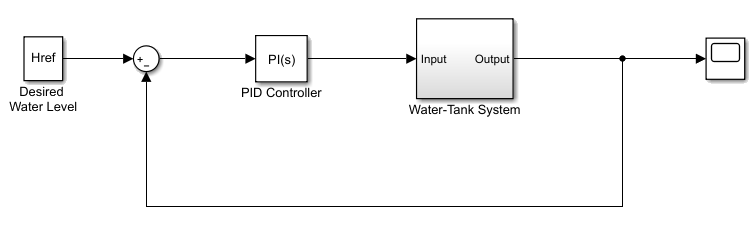

Modify the original model by making the following changes:

- Delete the PID Controller.

- Insert the RL Agent block.

- Connect the observation vector ${\left\lbrack \begin{array}{ccc}
\int e\;\textrm{dt} & e & h
\end{array}\right\rbrack }^{T\;}$, where $h$ is the height of the water in the tank, $e=r-h$, and $r$ is the reference height.

- Set up the reward $\textrm{reward}=10\left(\left|e\right|<0\ldotp 1\right)-1\left(\left|e\right|\ge 0\ldotp 1\right)-100\left(h\le 0\left|\right|h\ge 20\right)$.

- Configure the termination signal such that the simulation stops if $h\le 0$ or $h\ge 20$.

The resulting model is `rlwatertank.slx`. For more information on this model and the changes, see [Create Simulink Environment for Reinforcement Learning](docid:rl_ug#mw_0e8060ca-2e7a-4d41-90d1-3bf4aeb76099).

open_system("rlwatertank")

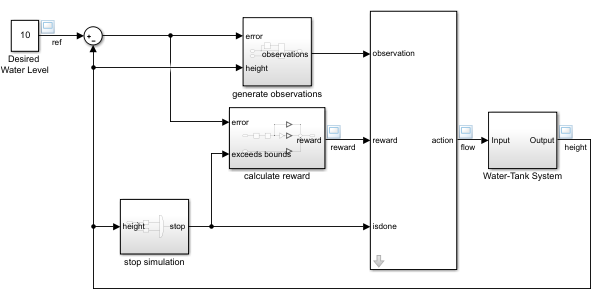

## Create the Environment

Creating an environment model includes defining the following:

- Action and observation signals that the agent uses to interact with the environment. For more information, see [rlNumericSpec](docid:rl_ref#mw_1a66fdf2-e758-4985-a541-61943fb15e79) and [rlFiniteSetSpec](docid:rl_ref#mw_68f70adf-d6a9-4cbe-846c-a7d0823c0774).

- Reward signal that the agent uses to measure its success. For more information, see [Define Reward Signals](docid:rl_ug#mw_1fe437df-5904-43dc-8b75-1e25bb9ae3ff).

Define the observation specification `obsInfo` and action specification `actInfo`.

% Observation info
obsInfo = rlNumericSpec([3 1],...
    LowerLimit=[-inf -inf 0  ]',...
    UpperLimit=[ inf  inf inf]');

% obsInfo = rlNumericSpec([2 1],...
%     LowerLimit=[-inf 0  ]',...
%     UpperLimit=[ inf inf]');

% Name and description are optional and not used by the software
obsInfo.Name = "observations";
obsInfo.Description = "integrated error, error, and measured height";

% Action info
actInfo = rlNumericSpec([1 1]);
actInfo.Name = "flow";

Create the environment object.

env = rlSimulinkEnv("rlwatertank","rlwatertank/RL Agent",...
    obsInfo,actInfo);

Set a custom reset function that randomizes the reference values for the model.

env.ResetFcn = @(in)localResetFcn(in);

Specify the simulation time `Tf` and the agent sample time `Ts` in seconds.

Ts = 1.0;
Tf = 200;

Fix the random generator seed for reproducibility.

rng(0)

## Create the Critic

DDPG agents use a parametrized Q-value function approximator to estimate the value of the policy. A Q-value function critic takes the current observation and an action as inputs and returns a single scalar as output (the estimated discounted cumulative long-term reward for which receives the action from the state corresponding to the current observation, and following the policy thereafter).

To model the parametrized Q-value function within the critic, use a neural network with two input layers (one for the observation channel, as specified by `obsInfo`, and the other for the action channel, as specified by `actInfo`) and one output layer (which returns the scalar value).

Define each network path as an array of layer objects. Assign names to the input and output layers of each path. These names allow you to connect the paths and then later explicitly associate the network input and output layers with the appropriate environment channel. Obtain the dimension of the observation and action spaces from the `obsInfo` and `actInfo` specifications. 

% Observation path
obsPath = [
    featureInputLayer(obsInfo.Dimension(1),Name="obsInLyr")
    fullyConnectedLayer(50)
    reluLayer
    fullyConnectedLayer(25,Name="obsPathOutLyr")
    ];

% Action path
actPath = [
    featureInputLayer(actInfo.Dimension(1),Name="actInLyr")
    fullyConnectedLayer(25,Name="actPathOutLyr")
    ];

% Common path
commonPath = [
    additionLayer(2,Name="add")
    reluLayer
    fullyConnectedLayer(1,Name="QValue")
    ];

criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork,obsPath);
criticNetwork = addLayers(criticNetwork,actPath);
criticNetwork = addLayers(criticNetwork,commonPath);

criticNetwork = connectLayers(criticNetwork, ...
    "obsPathOutLyr","add/in1");
criticNetwork = connectLayers(criticNetwork, ...
    "actPathOutLyr","add/in2");

View the critic network configuration.

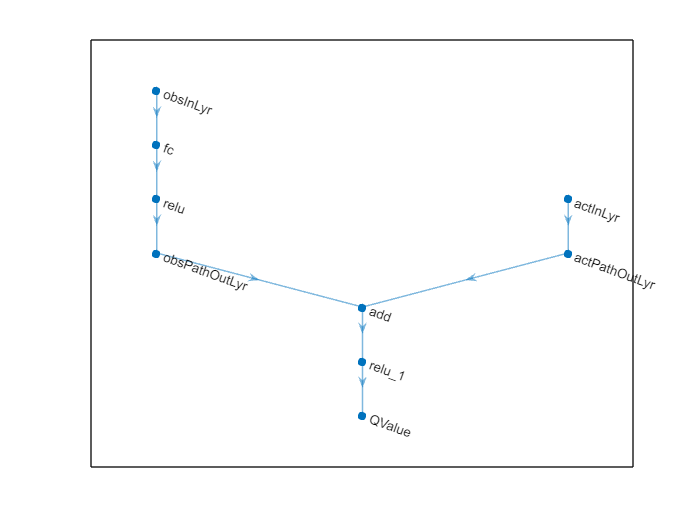

figure
plot(criticNetwork)

Convert the network to a `dlnetwork` object and summarize its properties.

criticNetwork = dlnetwork(criticNetwork);
summary(criticNetwork)

   Initialized: true

   Number of learnables: 1.5k

   Inputs:
      1   'obsInLyr'   3 features
      2   'actInLyr'   1 features



Create the critic approximator object using the specified deep neural network, the environment specification objects, and the names if the network inputs to be associated with the observation and action channels. 

critic = rlQValueFunction(criticNetwork, ...
    obsInfo,actInfo, ...
    ObservationInputNames="obsInLyr", ...
    ActionInputNames="actInLyr");

For more information on Q-value function objects, see [`rlQValueFunction`](docid:rl_ref#mw_e6e7abac-0a33-423b-8473-1409879db701).

Check the critic with a random input observation and action.

getValue(critic, ...
    {rand(obsInfo.Dimension)}, ...
    {rand(actInfo.Dimension)})

ans = single
-0.1631

For more information on creating critics, see [Create Policies and Value Functions](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004).

## Create the Actor

DDPG agents use a parametrized deterministic policy over continuous action spaces, which is learned by a continuous deterministic actor.

A continuous deterministic actor implements a parametrized deterministic policy for a continuous action space. This actor takes the current observation as input and returns as output an action that is a deterministic function of the observation.

To model the parametrized policy within the actor, use a neural network with one input layer (which receives the content of the environment observation channel, as specified by `obsInfo`) and one output layer (which returns the action to the environment action channel, as specified by `actInfo`).

Define the network as an array of layer objects.

actorNetwork = [
    featureInputLayer(obsInfo.Dimension(1))
    fullyConnectedLayer(3)
    tanhLayer
    fullyConnectedLayer(actInfo.Dimension(1))
    ];

Convert the network to a `dlnetwork` object and summarize its properties.

actorNetwork = dlnetwork(actorNetwork);
summary(actorNetwork)

   Initialized: true

   Number of learnables: 16

   Inputs:
      1   'input'   3 features



Create the actor approximator object using the specified deep neural network, the environment specification objects, and the name if the network input to be associated with the observation channel. 

actor = rlContinuousDeterministicActor(actorNetwork,obsInfo,actInfo);

For more information, see [`rlContinuousDeterministicActor`](docid:rl_ref#mw_c2909424-90f4-4a52-803b-73310483e6c3). 

Check the actor with a random input observation.

getAction(actor,{rand(obsInfo.Dimension)})

ans = 1×1 cell array
    {[-0.3408]}


For more information on creating critics, see [Create Policies and Value Functions](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004).

## Create the DDPG Agent

Create the DDPG agent using the specified actor and critic approximator objects.

agent = rlDDPGAgent(actor,critic);

For more information, see [`rlDDPGAgent`](docid:rl_ref#mw_7e49ed9c-eea8-4994-8532-c7f66d5359ef). 

Specify options for the agent, the actor, and the critic using dot notation.

agent.SampleTime = Ts;

agent.AgentOptions.TargetSmoothFactor = 1e-3;
agent.AgentOptions.DiscountFactor = 1.0;
agent.AgentOptions.MiniBatchSize = 64;
agent.AgentOptions.ExperienceBufferLength = 1e6; 

agent.AgentOptions.NoiseOptions.Variance = 0.3;
agent.AgentOptions.NoiseOptions.VarianceDecayRate = 1e-5;

agent.AgentOptions.CriticOptimizerOptions.LearnRate = 1e-03;
agent.AgentOptions.CriticOptimizerOptions.GradientThreshold = 1;
agent.AgentOptions.ActorOptimizerOptions.LearnRate = 1e-04;
agent.AgentOptions.ActorOptimizerOptions.GradientThreshold = 1;

Alternatively, you can specify the agent options using an [`rlDDPGAgentOptions`](docid:rl_ref#mw_5e9a4c5d-03d5-48d9-a85b-3c2d25fde43c) object.

Check the agent with a random input observation.

getAction(agent,{rand(obsInfo.Dimension)})

ans = 1×1 cell array
    {[-0.7926]}


## Train Agent

To train the agent, first specify the training options. For this example, use the following options:

- Run each training for at most 5000 episodes. Specify that each episode lasts for at most `ceil(Tf/Ts)` (that is 200) time steps.

- Display the training progress in the Episode Manager dialog box (set the `Plots` option) and disable the command line display (set the `Verbose` option to `false`).

- Stop training when the agent receives an average cumulative reward greater than 800 over 20 consecutive episodes. At this point, the agent can control the level of water in the tank.

For more information, see [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0).

trainOpts = rlTrainingOptions(...
    MaxEpisodes=5000, ...
    MaxStepsPerEpisode=ceil(Tf/Ts), ...
    ScoreAveragingWindowLength=20, ...
    Verbose=false, ...
    Plots="training-progress",...
    StopTrainingCriteria="AverageReward",...
    StopTrainingValue=800);

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Training is a computationally intensive process that takes several minutes to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

doTraining = true;

if doTraining
    % Train the agent.
    trainingStats = train(agent,env,trainOpts);
else
    % Load the pretrained agent for the example.
    load("WaterTankDDPG.mat","agent");
end

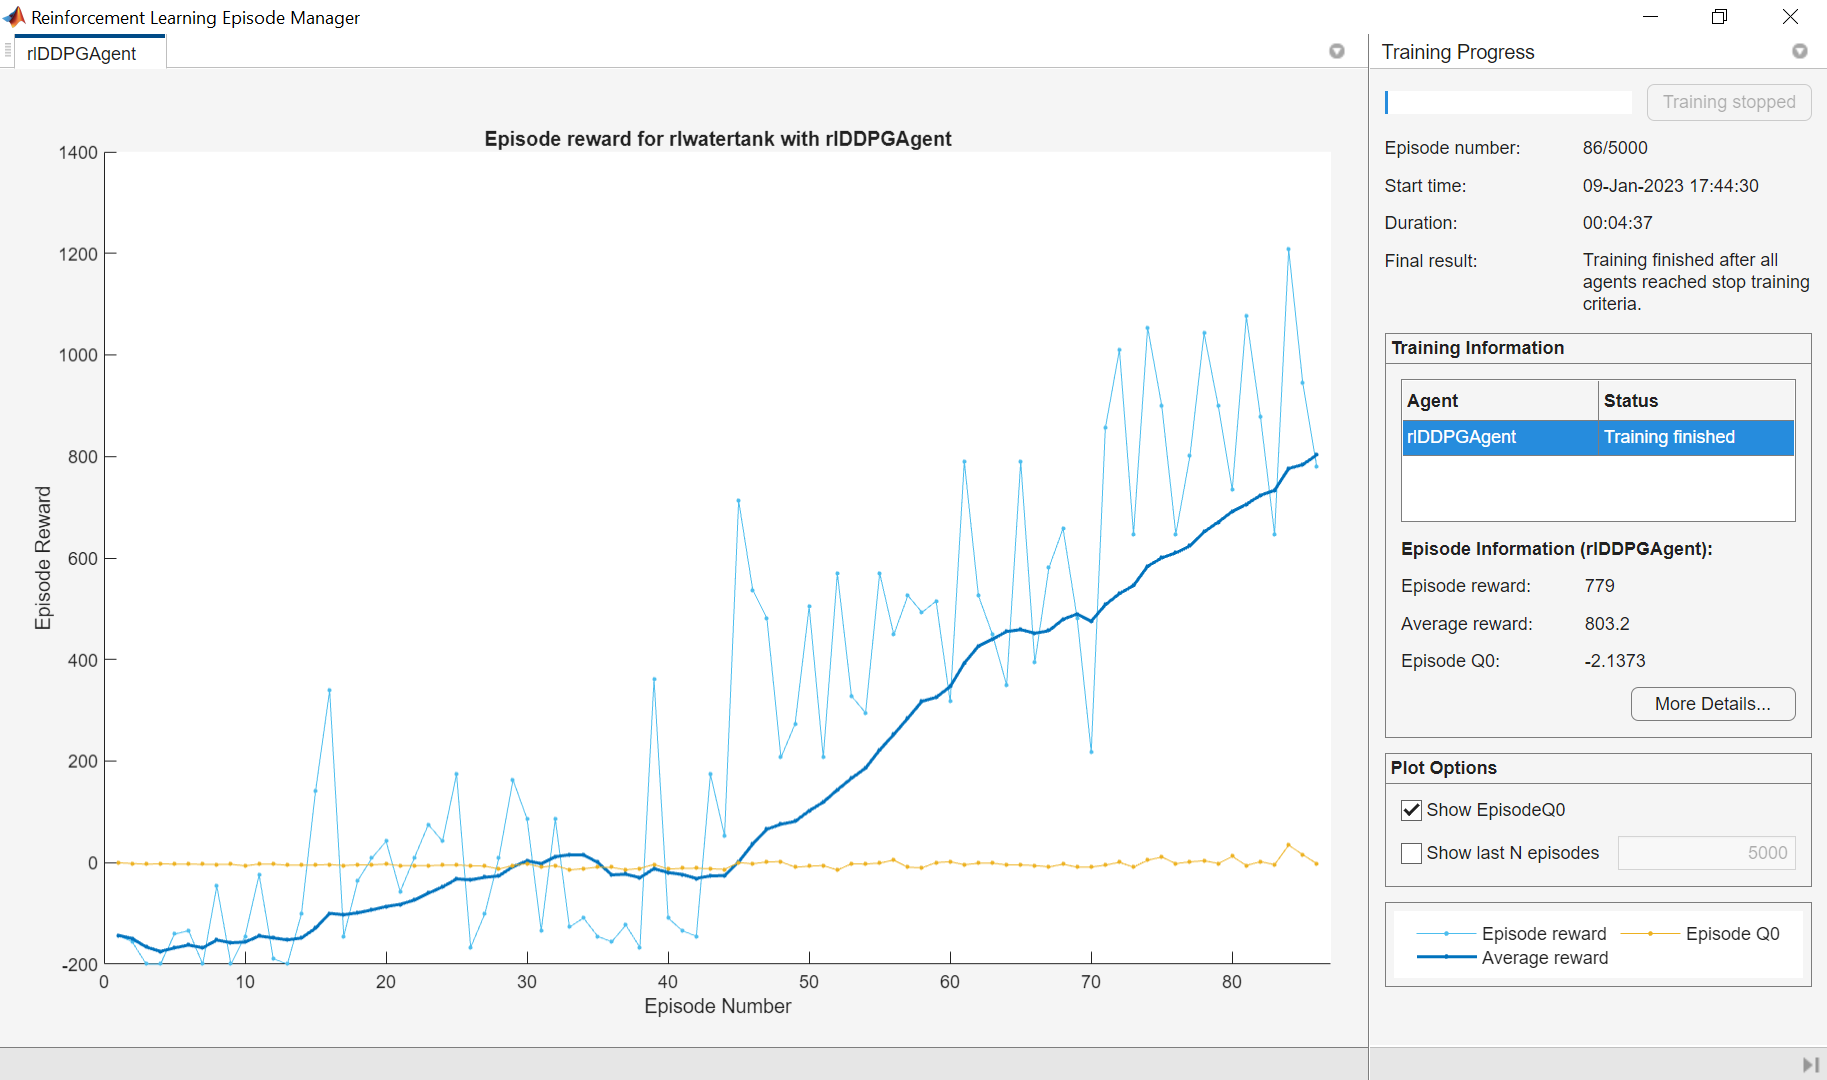

## Validate Trained Agent

Validate the learned agent against the model by simulation. Since the reset function randomizes the reference values, fix the random generator seed to ensure simulation reproducibility.

rng(1)

Simulate the agent within the environment, and return the experiences as output.

simOpts = rlSimulationOptions(MaxSteps=ceil(Tf/Ts),StopOnError="on");
experiences = sim(env,agent,simOpts);

Dot indexing is not supported for variables of this type.

Error in rl.util.expstruct2timeserstruct (line 7)
observation     = {experiences.Observation}; 

Error in rl.env.AbstractEnv/sim (line 130)
            s = rl.util.expstruct2timeserstruct(exp,time,oinfo,ainfo);

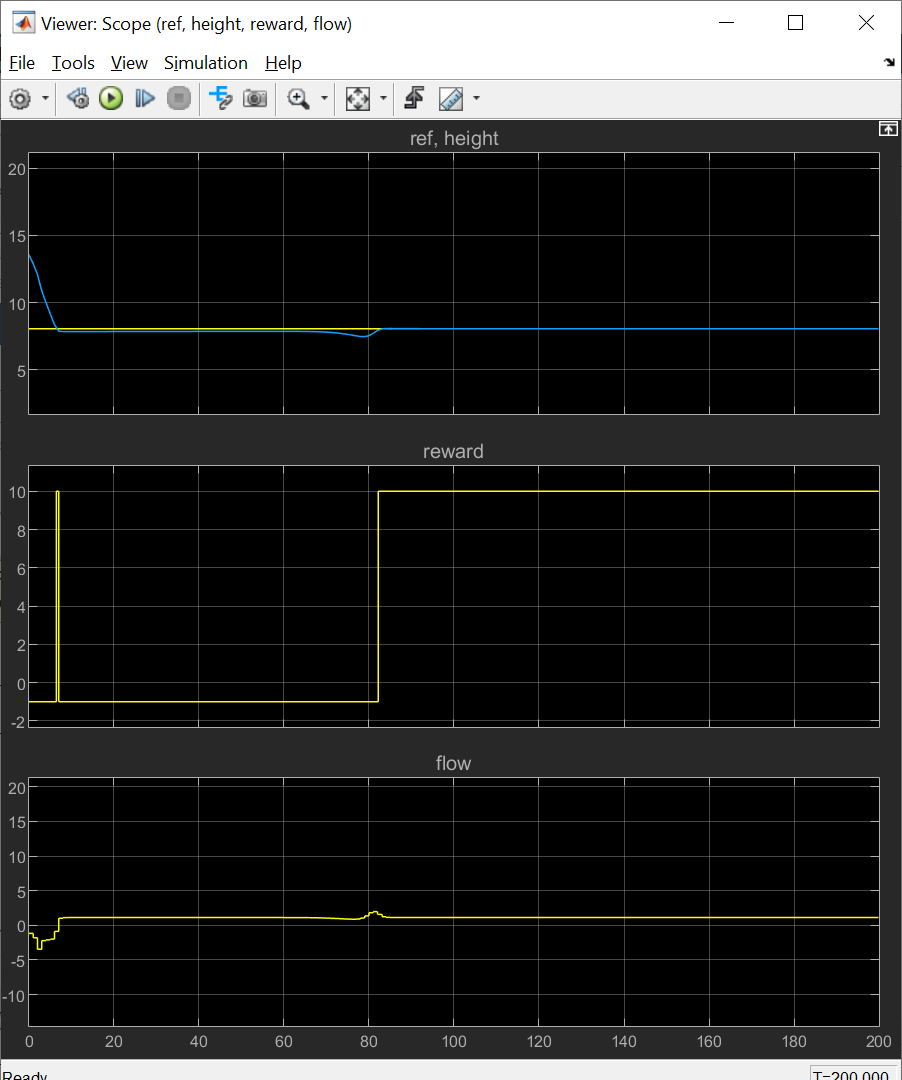

## Local Reset Function

function in = localResetFcn(in)

% Randomize reference signal
blk = sprintf("rlwatertank/Desired \nWater Level");
h = 3*randn + 10;
while h <= 0 || h >= 20
    h = 3*randn + 10;
end
in = setBlockParameter(in,blk,Value=num2str(h));

% Randomize initial height
h = 3*randn + 10;
while h <= 0 || h >= 20
    h = 3*randn + 10;
end
blk = "rlwatertank/Water-Tank System/H";
in = setBlockParameter(in,blk,InitialCondition=num2str(h));

end

*Copyright 2019 - 2023 The MathWorks, Inc.*